# Init

clear
addpath 'Functions'
addpath 'Functions/reticolo_allege'

# Optimization using genetic algorithm

if max(size(gcp)) == 0 % parallel pool needed
    parpool('local',12);
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


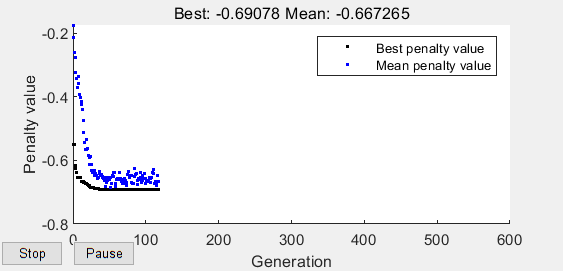

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
and constraint violation is less than options.ConstraintTolerance.


x =    184    11    48    82   109   179


load('Functions\OptParm.mat','OptParm')
fun = @(x) -FigureOfMerit1D(x,OptParm);
nvars = length(x0);
IntCon = 1:nvars;
A = [];
b = [];
Aeq = [];
beq = [];
lb = zeros(1,nvars);
ub = (OptParm.Geometry.Level-1)*ones(1,nvars);
nonlcon = [];
options = optimoptions('ga',...
    'UseParallel', true,...
    'PlotFcn','gaplotbestf',...
    'MaxTime',6000);
figure('Position',[0 0 250 150])
x = ga(fun,nvars,A,b,Aeq,beq,lb,ub,nonlcon,IntCon,options)


save("StructureGA.mat",'x')

# Simulation validation

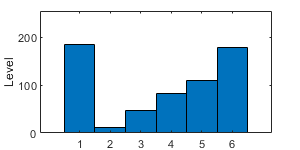

% 读取
load("StructureGA.mat",'x')
load('Functions\OptParm.mat','OptParm')
% 波长
wavelength_list = [1500,1550,1600];
% 无偏差
OptParm.Optimization.Robustness.StartDeviation = [0]; % Starting height deviation values
OptParm.Optimization.Robustness.Weights = [1];
% 遍历
FOM_list = zeros(length(wavelength_list),2);
for ii = 1:length(wavelength_list)
    OptParm.Input.Wavelength = wavelength_list(ii);
    OptParm.Input.Polarization = 'TM';
    FOM_list(ii,1) = FigureOfMerit1D(x,OptParm);
    OptParm.Input.Polarization = 'TE';
    FOM_list(ii,2) = FigureOfMerit1D(x,OptParm);
end
% 显示结构
figure('Position',[0 0 300 150])
bar(x,1)
ylabel('Level')
ylim([0 (OptParm.Geometry.Level-1)])

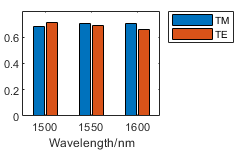


figure('Position',[0 0 250 150])
bar(wavelength_list,FOM_list);
xlabel('Wavelength/nm')
legend('TM','TE','Location','northeastoutside')

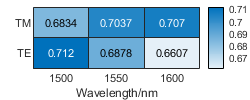


figure('Position',[0 0 250 100])
heatmap(wavelength_list,{'TM','TE'},FOM_list')
xlabel('Wavelength/nm')